% clear;clc;close all;
set(0, 'defaultlinelinewidth', 1)
set(0, 'defaultaxeslinewidth', 2);
set(0, 'defaultaxesfontsize', 28);
set(0, 'defaulttextfontsize', 28);
set(0, 'DefaultLineMarkerSize', 10);
set(0, 'Defaultaxesfontname', 'Times New Roman');

parpool(8)

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).

ans = 

 ProcessPool with properties: 

            Connected: true
           NumWorkers: 8
              Cluster: 

定义 Weierstrass 函数

a = 0.5;
b = 7;
a*b-1-3/2*pi

ans = -2.2124

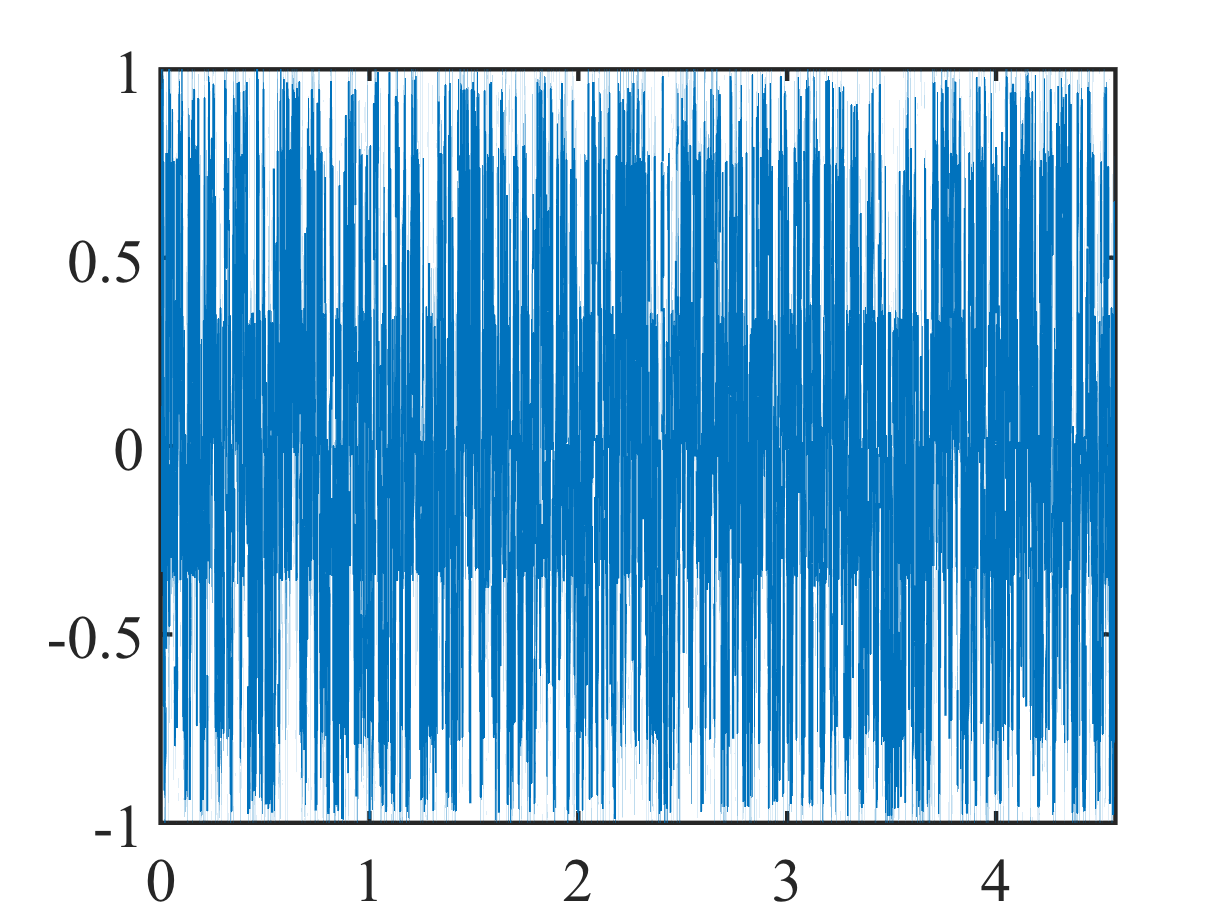

iter = 15;
long = 32/b;
n = 1e6;
randLenth = 0.003;
randN = floor(randLenth * n / long);
x = linspace(0, long, n);
y = 0;
for i = 1:iter
    y = a^i * cos(b^i*pi*x) + y;
end

loca = 1;
a1 = 0.1;
for i = 1:n
    yNew(i) = y(loca);
    loca = loca + randi([-randN randN],1,1);
    loca = mod(loca,n);
    if (loca == 0)
        loca = 1;
    end
end
y = yNew;

plot(x, y);

结构函数


stru = 0;
parfor j = 1:n-1
    squarAll = 0;
    for i = 1:n-j
        squarAll = squarAll + (y(i+j)-y(i))^2;
    end
    stru(j) = squarAll/(n-j);
end

plot(x(1:floor((end-1)/2)), stru(1:floor((end)/2)));






























